# Image Classification using 2D CNN

Load Training DATA set

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet', ...
    'nndemos','nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

Validate Data

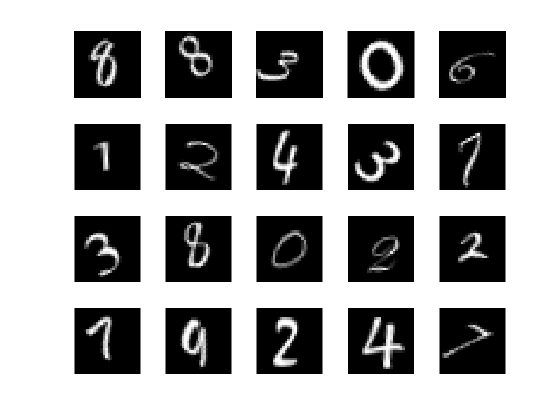

figure
numImages = 10000;
perm = randperm(numImages,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Create Architecture

layers = [ ...
    imageInputLayer([28 28 1])
    convolution2dLayer(5,20)
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

Check Optimization

options = trainingOptions('sgdm', ...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4, ...
    'Verbose',false, ...
    'Plots','training-progress');

Tarin Network

numTrainingFiles = 750;
[imdsTrain,imdsTest] = splitEachLabel(imds,numTrainingFiles,'randomize');

net = trainNetwork(imdsTrain,layers,options);

Unrecognized function or variable 'imdsTrain'.

Evaluate Trained Model

YPred = classify(net,imdsTest);
YTest = imdsTest.Labels;

accuracy = sum(YPred == YTest)/numel(YTest)


Test Model using Test DATA